clear; clc;

#### Definições iniciais do problema

vol_max = 10000;
vol_tank = 0;
flux_max = 15;
limiar = 6000;
tempo = 300;
erro_domain  = [-limiar vol_max-limiar];
domain_cons  = [-flux_max flux_max];
res_interval = [-flux_max:0.1:flux_max];

#### Define vetor de fluxo da entrada

Realiza mudanças de forma randomica e contínua no fluxo de entrada

lastPos = 0;  flux = [];
for idx = 0:1:tempo
    target = randsample(flux_max, 1);
    if(lastPos > target)
        step = -1;
    else
        step = 1;
    end
    
    for item = lastPos:step:target
        flux = [flux item];
    end
    lastPos = item;
end

#### Define funções de pertinência que atuarão sobre o problema

Define as funções de pertinência de acordo com o problema. 

Para isso, trabalharemos com o erro do sistema em relação ao limiar

err_min = min(erro_domain);
err_max = max(erro_domain);
func_div = (err_max - err_min) / 5;

antecedent = {@(x)gaussian(x, err_min, func_div)  ...
    @(x)gaussian(x, err_min + abs(err_min/2), abs(err_min/2)), ...
    @(x)gaussian(x, 0, func_div), ...
    @(x)gaussian(x, abs(err_max/2), abs(err_max/2))...
    @(x)gaussian(x, err_max, func_div)};
    
 
funC_div = flux_max/3;
consequent = {    
    @(x)gaussian(x,-flux_max, funC_div*2) ...
    @(x)gaussian(x,-funC_div*1.3, funC_div*1.2) ...
    @(x)gaussian(x, 0, funC_div) ...
    @(x)gaussian(x,funC_div*1.2, funC_div*1.2) ...
    @(x)gaussian(x,flux_max, funC_div*2)};

Plota os gráficos das funções de pertinência do antecedente e consequente

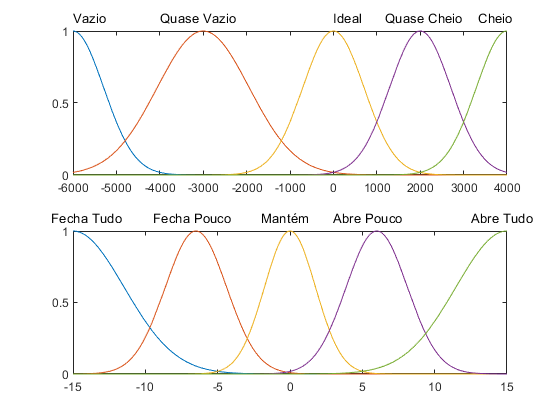

figure(1);
subplot(2,1,1)
for i= 1:1:length(antecedent)
    fplot(@(x)antecedent{i}(x), erro_domain); hold on;
end

text(err_min, 1.1, "Vazio");
text(0-4, 1.1, "Ideal");
text(err_min + abs(err_min/2) - abs(err_min/2)/3, 1.1, "Quase Vazio");
text(abs(err_max/2) - abs(err_max/2)/2.5, 1.1, "Quase Cheio");
text(err_max/1.2, 1.1, "Cheio");
hold off;

subplot(2,1,2)
for i= 1:1:length(consequent)
    fplot(@(x)consequent{i}(x), domain_cons); hold on;
end

text(-flux_max*1.1, 1.1, "Fecha Tudo");
text(-funC_div*1.9, 1.1,"Fecha Pouco");
text(-2, 1.1,"Mantém");
text(funC_div*0.6, 1.1,"Abre Pouco");
text(flux_max-funC_div/2, 1.1,"Abre Tudo");
hold off;

#### Define as regras de inferência da solução

- Se Vazio, então Fecha Tudo

- Se Quase vazio, então Fecha Pouco

- Se Ideal, então Mantém

- Se Quase Cheio, então Abre Pouco

- Se Cheio, então Abre Tudo

rules = {@(x,k)minIntersection(x,consequent{1},antecedent{1}(k)), ...
         @(x,k)minIntersection(x,consequent{2},antecedent{2}(k)), ...
         @(x,k)minIntersection(x,consequent{3},antecedent{3}(k)), ...
         @(x,k)minIntersection(x,consequent{4},antecedent{4}(k)), ...
         @(x,k)minIntersection(x,consequent{5},antecedent{5}(k))};

#### Calcula a saída do sistema para o vetor de fluxos

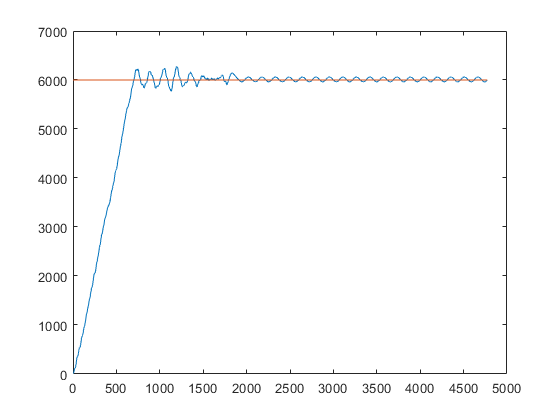

current_flux = 0; vol_historic = []; out_historic = [];
for i = 1:1:length(flux)
    vol_historic = [vol_historic vol_tank];
    vol_tank = vol_tank + flux(i);
    
    current_error = vol_tank - limiar;
    
    res = maxUnion(rules, current_error, res_interval);
    outDeff = defuzz(res_interval, res, 'centroid');
    out_historic = [out_historic outDeff];
    
    current_flux = replaceFlux(current_flux, outDeff, flux_max);
    vol_tank = vol_tank - current_flux;
end
figure(2);
lim = linspace(limiar,limiar,length(vol_historic));
plot(vol_historic+10); hold on;
plot(lim); hold off;

#### Análise

Análise estatística dos resultados encontrados

vec_analisis = vol_historic(300:900)+9;
datMedi = mean(vec_analisis);            
datStd  = std(vec_analisis);             
datVar  = var(vec_analisis);            
datCoe  = corrcoef(vec_analisis);
disp("Media: "+datMedi + " | Desvio: "+datStd+" | Variância: "+datVar+" | Coef: "+datCoe);

Media: 4852.0788 | Desvio: 1185.106 | Variância: 1404476.2826 | Coef: 1


#### Funções de Pertinência

Definição da função Triangular

function res = triangle(x,a,m,b)
res = max(min((x-a)/(m-a), (b-x)/(b-m)), 0);
end

Definição da função Trapezoidal

function res = trapezoidal(x,a,m,n,b)
    a = min((x-a)./(m-a), (b-x)./(b-n));
    res = max(min(a, 1), 0);
end

Definição da função Gaussiana

function res = gaussian(x, m, k)
    k = k/2;
    res = exp((-(x-m).^2)/(k^2));
end

#### Funçoes de Intercessão ( T - normas )

Zadeh - min

function res = minIntersection(x, func1, val)
    res = min(func1(x), val);
end

#### Funções de União (S - normas)

Zadeh - max

function res = maxUnion(rules, error, interval)
    res = []; aux = 0; bef = 0;
    for i = 1:1:length(interval)
        for j = 1:1:length(rules)
            bef = rules{j}(interval(i), error);
            aux = max(aux, bef);
        end
        res = [res aux];
        aux = 0; bef = 0;
    end
end

#### Função de ajuste do erro

function res = replaceFlux(currentFlux, out, flux_max)
    currentFlux = currentFlux + out;
    if (currentFlux < 0)
        res = 0;
    elseif (currentFlux > flux_max)
        res = flux_max;
    else
        res = currentFlux;
    end
end